# Support Vector Machines

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

Use the whole dataset (without splitting) to train a standard Support Vector Machine (SVM) and visualise its linear decision boundary. Note that the dataset has already been z-score standardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset using default hyperparameters [2 marks]

- Generating a "grid" of testing data which spans the minimum and maximum value of each feature in the training dataset [8 marks]

- Using your trained SVM to classify the testing data you have generated [2 marks]

- Generating a scatter plot of your testing data, with each point colour-coded by the associated classification result [2 marks]

- Superimposing the original training data so that it is clearly visible [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

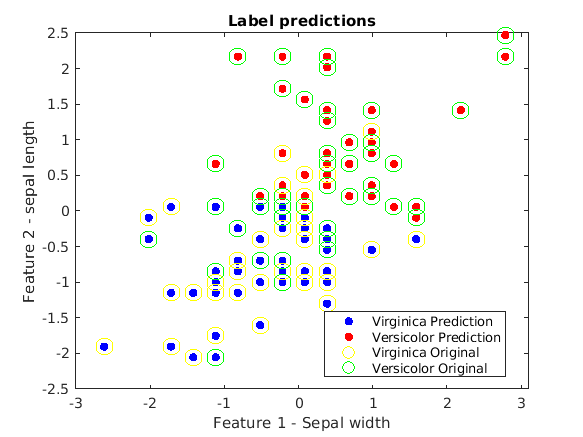

% add as many lines of code as you need below:
%train an SVM on the whole dataset
m = fitcsvm(examples, labels);
%generating a grid of testing data
%changing the table to array
arr = table2array(examples);
%for loop to create the grid
for i = 1:100
    for j = 1:2
        Grid(i,j) = meshgrid(min(arr(i,j):1:max(arr(i,j))));
    end
end
%split the grit into feature value 1 and feature value 2
Grid = [Grid];
grid_a = Grid(:,1);
grid_b = Grid(:,2);
%classifying the testing data
predictions = predict (m,Grid);
%generating a scatter plot to show predicted data and superimposing the
%original training data so that it is clearly visible
figure;
gscatter(grid_a,grid_b,predictions,'br');
hold on
gscatter(arr(:,1),arr(:,2),labels,'yg','o',12);
hold off
title("Label predictions")
xlabel("Feature 1 - Sepal width")
ylabel("Feature 2 - sepal length")
legend('Virginica Prediction','Versicolor Prediction','Virginica Original','Versicolor Original')